%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%VIENNE Carmelle - MALYQUEVIQUE Anaë - LAMONICA Clara - COUTURIER Marie
%Projet MUTTIN 2020
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Détermination des constantes%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %Conductivité thermique de l'aluminium
% k = 237;
% %Masse volumique de l'aluminium
% rho = 2700;
% %Capacité thermique massique de l'aluminium
% c = 897;

%Conductivité thermique de céramique
k = 160;
%Masse volumique de céramique
rho = 3260;
%Capacité thermique massique de céramique
c = 800;

%Température sur le contour
T0 = 185;
%Longueur h en mm
h = 10E-3;   
-rho*c/k

ans = -16300

## A


%Matrice des coefficients devant les inconnues A
% A = [-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1, 0, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0, 1, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 0, 0, 1;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1, 0;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4, 1;
%       0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1,-4;];
A1=diag(-4*ones(3,1))+diag(ones(2,1),-1)+diag(ones(2,1),1)

A1 =     -4     1     0
     1    -4     1
     0     1    -4


A2=diag(ones(3,1))

A2 =      1     0     0
     0     1     0
     0     0     1


A3=zeros(3)

A3 =      0     0     0
     0     0     0
     0     0     0


A=[A1 A2 A3 A3 A3 A3 A3 A3 A3;
   A2 A1 A2 A3 A3 A3 A3 A3 A3;
   A3 A2 A1 A2 A3 A3 A3 A3 A3;
   A3 A3 A2 A1 A2 A3 A3 A3 A3;
   A3 A3 A3 A2 A1 A2 A3 A3 A3;
   A3 A3 A3 A3 A2 A1 A2 A3 A3;
   A3 A3 A3 A3 A3 A2 A1 A2 A3;
   A3 A3 A3 A3 A3 A3 A2 A1 A2;
   A3 A3 A3 A3 A3 A3 A3 A2 A1]

A =     -4     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0    -4     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1    -4     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     1    -4     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0

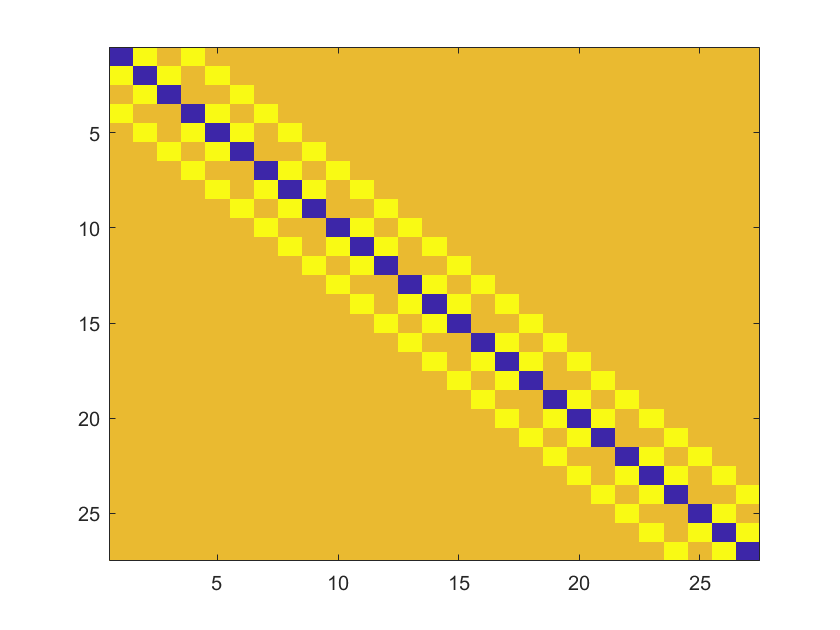

imagesc(A)

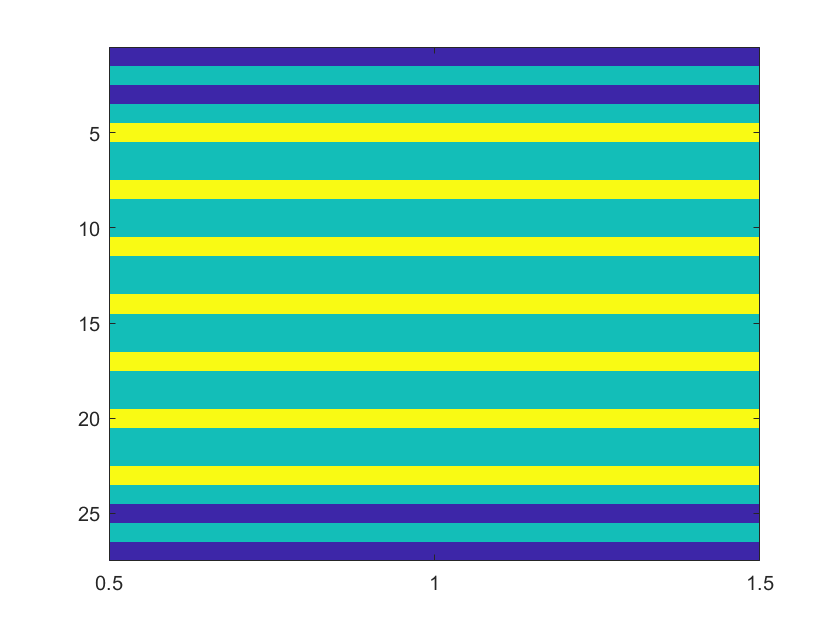

  
%Matrice des constantes C
C = [((-rho*c*h)/k)-370; ((-rho*c*h)/k)-185; ((-rho*c*h)/k)-370;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-185; ((-rho*c*h)/k); ((-rho*c*h)/k)-185;
    ((-rho*c*h)/k)-370; ((-rho*c*h)/k)-185; ((-rho*c*h)/k)-370;];
imagesc(C)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Résolution du système%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
U = A\C

U =   315.5055
  353.5737
  315.5055
  375.4481
  435.2841
  375.4481
  403.0028
  473.6663
  403.0028
  414.8968



Z=zeros(11,5) %la matrice finale que l'on va tracer

Z =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



for i=2:10
    Z(i, 2:4)=U(1+3*(i-2):3+3*(i-2));
end
Z(1,:)=T0;
Z(11,:)=T0;
Z(:,1)=T0;
Z(:,5)=T0;
Z

Z =   185.0000  185.0000  185.0000  185.0000  185.0000
  185.0000  315.5055  353.5737  315.5055  185.0000
  185.0000  375.4481  435.2841  375.4481  185.0000
  185.0000  403.0028  473.6663  403.0028  185.0000
  185.0000  414.8968  490.3756  414.8968  185.0000
  185.0000  418.2090  495.0423  418.2090  185.0000
  185.0000  414.8968  490.3756  414.8968  185.0000
  185.0000  403.0028  473.6663  403.0028  185.0000
  185.0000  375.4481  435.2841  375.4481  185.0000
  185.0000  315.5055  353.5737  315.5055  185.0000


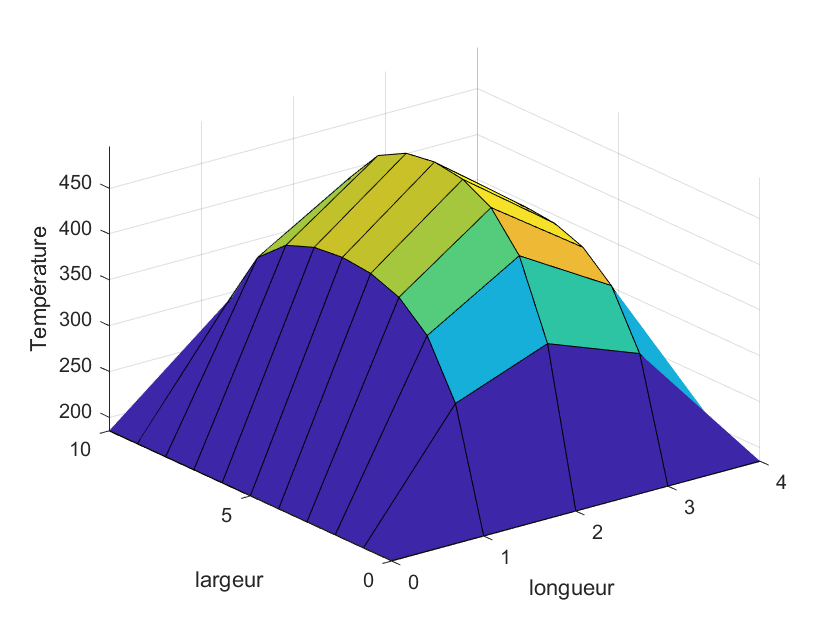


figure(1)
[xq,yq] = meshgrid(0:4, 0:10);
surfc(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

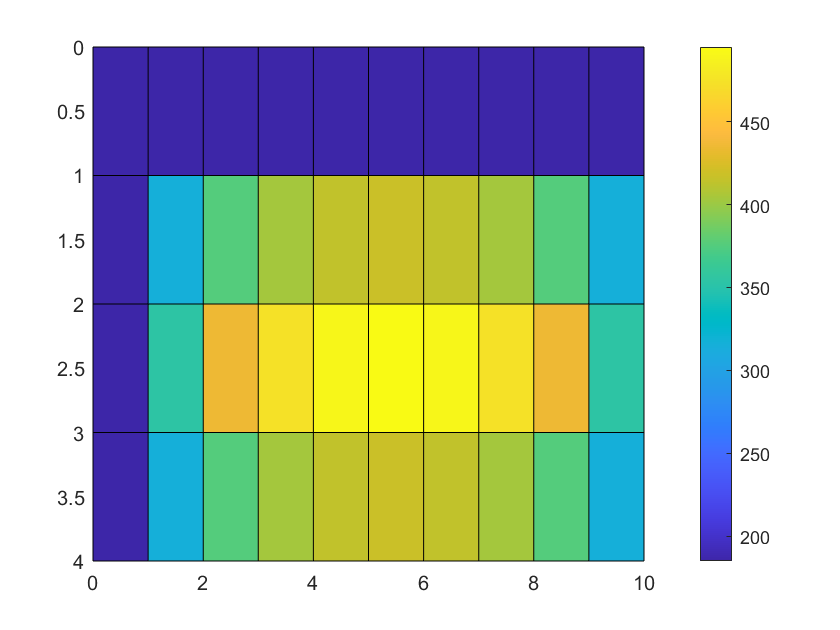



figure(2)
[xq,yq] = meshgrid(0:4, 0:10);
surf(xq,yq,Z)
view([90,90])
colorbar


figure(3)
[xqq,yqq] = meshgrid(0:.2:4, 0:.2:10); %précision d'interpolation
vq = griddata(xq,yq,Z,xqq,yqq,'cubic')

vq =   185.0000  183.6079  180.8238  178.7357  179.4318  185.0000  190.1622  190.0461  187.3489  184.7678  185.0000  187.0303  188.0455  188.0455  187.0303  185.0000  185.4638  189.4370  193.1782  192.9463  185.0000
  183.6079  185.1088  185.0773  186.2181  191.9603  206.7785  214.3840  217.0578  217.0769  216.7848  218.7994  220.9678  222.1033  221.8335  219.1186  214.4343  213.0707  215.1032  216.1843  210.6928  192.7130
  180.8238  185.0773  188.0935  195.4404  215.0473  234.6749  244.4618  249.5322  251.2080  253.0318  255.7290  258.2660  259.4220  256.6864  250.6095  244.1563  241.4610  241.4551  235.9773  216.2071  192.4782
  178.7357  186.2181  195.4404  217.0923  243.7974  264.7326  276.4873  282.7893  286.6309  290.0323  292.6163  295.1887  294.0524  288.1825  280.7916  272.2117  267.6053  261.4659  241.9412  215.0189  188.3870
  179.4318  191.9603  215.1330  243.9465  271.6639  292.9950  306.0485  314.5100  320.3867  323.9852  326.2887  327.5652  323.6633  316.7474  307.4223 

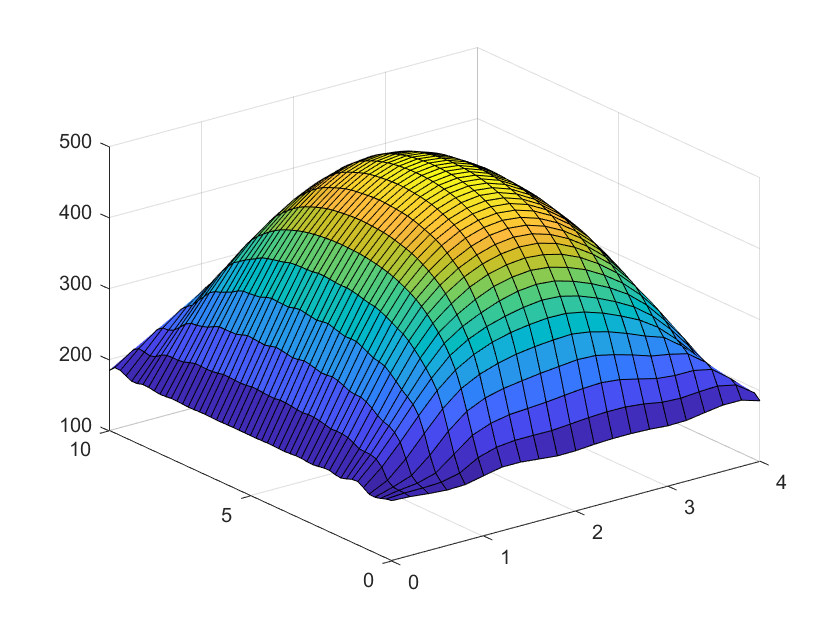

surf(xqq,yqq,vq)